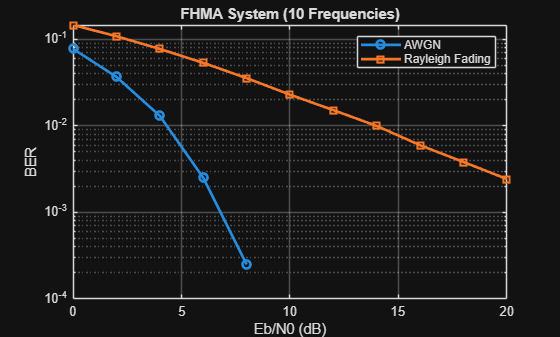

clc; clear; close all;

%% Parameters
N = 1e5;                  % Number of bits
EbN0_dB = 0:2:20;
numFreq = 10;             % Number of hopping frequencies

% Generate data
bits = randi([0 1], N, 1);
symbols = 2*bits - 1;     % BPSK

% Generate hopping pattern
hop_pattern = randi([1 numFreq], N, 1);

ber_awgn = zeros(size(EbN0_dB));
ber_rayleigh = zeros(size(EbN0_dB));

%% ================= Simulation =================
for i = 1:length(EbN0_dB)
    
    EbN0 = 10^(EbN0_dB(i)/10);
    noise_var = 1/(2*EbN0);
    
    err_awgn = 0;
    err_ray = 0;
    
    for k = 1:N
        
        freq = hop_pattern(k);   % selected carrier
        
        % Represent frequency channel as independent path
        h_freq = 1;  % AWGN case
        
        %% ================= AWGN =================
        noise = sqrt(noise_var)*randn;
        rx_awgn = h_freq * symbols(k) + noise;
        
        detected = sign(rx_awgn);
        if detected == 0, detected = 1; end
        
        if detected ~= symbols(k)
            err_awgn = err_awgn + 1;
        end
        
        %% ================= Rayleigh =================
        % Independent fading per frequency
        h = (randn + 1j*randn)/sqrt(2);
        
        noise = sqrt(noise_var)*(randn + 1j*randn);
        rx_ray = h * symbols(k) + noise;
        
        % Equalization
        rx_eq = real(rx_ray / h);
        
        detected = sign(rx_eq);
        if detected == 0, detected = 1; end
        
        if detected ~= symbols(k)
            err_ray = err_ray + 1;
        end
        
    end
    
    ber_awgn(i) = err_awgn / N;
    ber_rayleigh(i) = err_ray / N;
    
end

%% ================= Plot =================
figure;
semilogy(EbN0_dB, ber_awgn, 'o-', 'LineWidth', 2); hold on;
semilogy(EbN0_dB, ber_rayleigh, 's-', 'LineWidth', 2);

grid on;
xlabel('Eb/N0 (dB)');
ylabel('BER');
title(['FHMA System (', num2str(numFreq), ' Frequencies)']);
legend('AWGN','Rayleigh Fading');